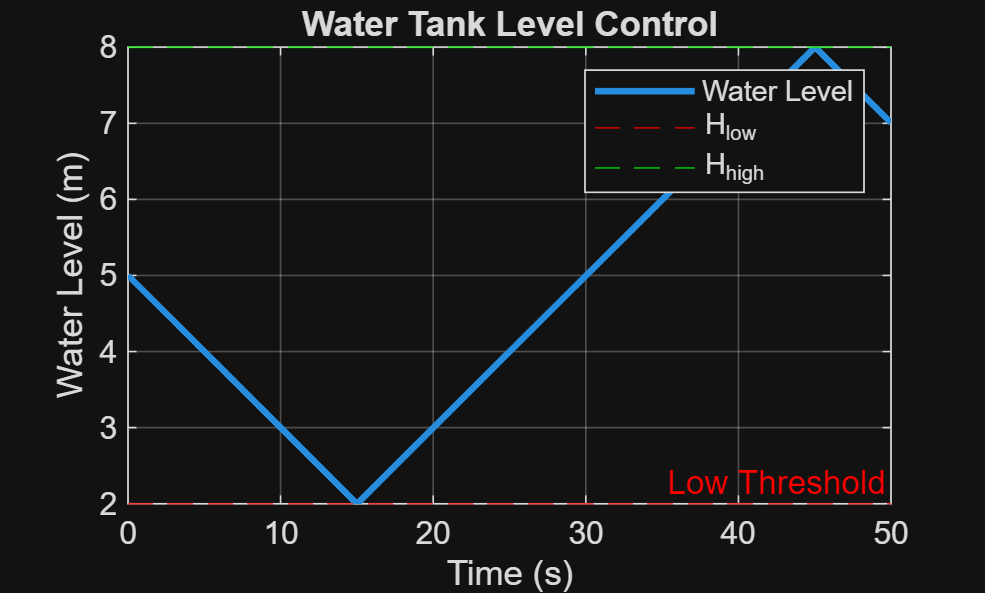

clc; clear; close all;

% Parameters
A = 1.5;                % Tank area (m^2)
Qin_max = 0.6;          % Max inflow (m^3/s)
Qout = 0.3;             % Constant outflow (m^3/s)

H_low = 2;              % Lower threshold (m)
H_high = 8;             % Upper threshold (m)

t_end = 50;             % Simulation time (s)
dt = 0.01;              % Time step

% Initialization
t = 0:dt:t_end;
H = zeros(size(t));
H(1) = 5;               % Initial level

Qin = 0;                % Initial inflow

% Simulation loop
for i = 1:length(t)-1
    
    % Control Logic
    if H(i) <= H_low
        Qin = Qin_max;   % Turn ON filling
    elseif H(i) >= H_high
        Qin = 0;         % Turn OFF filling
    end
    
    % Tank dynamics
    dHdt = (Qin - Qout) / A;
    H(i+1) = H(i) + dHdt * dt;
    
end

% Plot
figure;
plot(t, H, 'LineWidth', 2);
hold on;
yline(H_low, '--r', 'Low Threshold');
yline(H_high, '--g', 'High Threshold');

xlabel('Time (s)');
ylabel('Water Level (m)');
title('Water Tank Level Control');
legend('Water Level', 'H_{low}', 'H_{high}');
grid on;